## the ultimate solution

s_o=3;
A=@(w) exp(w);
C=@(w) sqrt(A(-w))./(1+sqrt(A(-w)));
b=@(w) w.^(2+s_o).*C(w).*(1-C(w))./(C(w)+(1-C(w)).*A(-w)) .* ...
    (A(2*w)./abs(1-A(w)).^3 + A(-3*w)./abs(1-A(-w)).^3);
ww=0:1e-5:10;
wopt=ww(b(ww)==max(b(ww)))

wopt = 5.2706

copt=C(wopt)

copt = 0.0669

bopt=b(wopt)

bopt = 18.4880

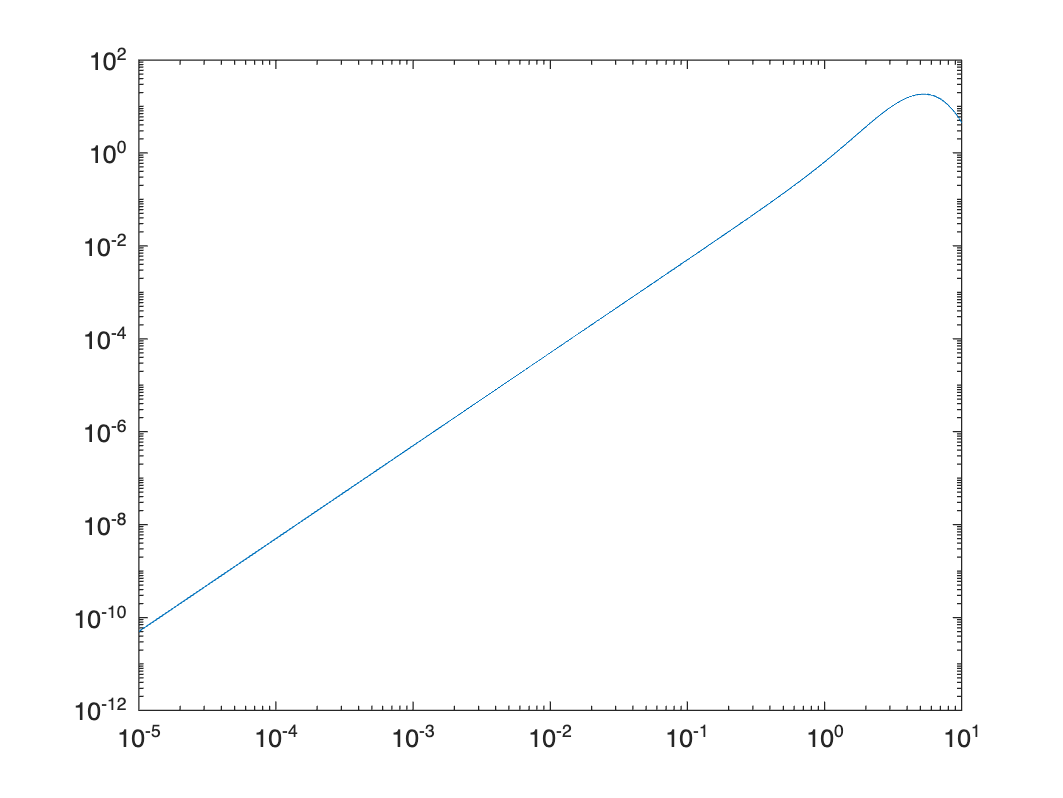

figure
loglog(ww,b(ww))

syms x
f(x)

## Analytics

syms D d w n
assume(n,'integer')
assume(D,'integer')
assume(d,'integer')
assume(d<=D & d>=0)
assume(w>0)
p=1/(d+(D-d)*exp(-w));
    F=d*(D-d)*w^2 * ( p*exp(2*w)/(exp(w)+1)^3 ...
        + (1-d*p)/(D-d)*exp(-2*w)/(exp(-w)+1)^3);
dwF=simplify(diff(F,w))
syms FF(w)
eqn=diff(FF)==dwF
simplify(dsolve(eqn,'Implicit',true))

ddWF=dwF*(exp(w)+1)^4*(D-d+d*exp(w))^2 ...
/(d*w*exp(w)*(D-d));
matlab2mathe

% Compute simplified symbolic expression
ddWF
simplifiedExpr = simplifyFraction(ddWF)

function [F] = FI(w,D,d)
    p=1/(d+(D-d)*exp(-w));
    F=d*(D-d)*w^2 * ( p*exp(2*w)/(exp(w)+1)^3 ...
        + (1-d*p)/(D-d)*exp(-2*w)/(exp(-w)+1)^3);
end
